# Grabación de audio

Establece la frecuencia de muestreo

fs = 16000

fs = 16000

Crea un objeto *audiorecorder*

grabacion = audiorecorder(fs,8,1)

grabacion =   audiorecorder with properties:

       SampleRate: 16000
    BitsPerSample: 8
      NumChannels: 1
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 0
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audiorecorder'


Graba 3 segundos de audio

record(grabacion,3);

Reproduce los 3 segundos de audio

play(grabacion);

Grafica el audio grabado

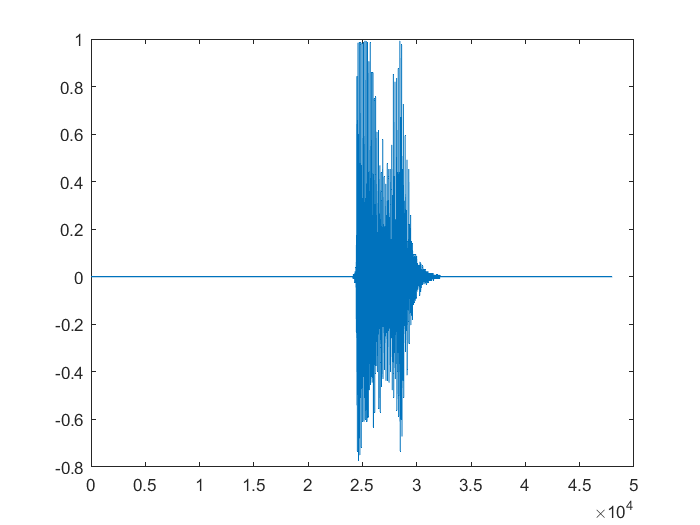

audioData = getaudiodata(grabacion);
%time = linspace(0,5,size(audioData,1));
plot(audioData)

Aquellas zonas con silencios no son relevantes (valores del audio en cero). Para detectar el inicio y final de la palabra se obtiene la zona en donde el audio es diferente de cero y se asigna a una nueva variable.

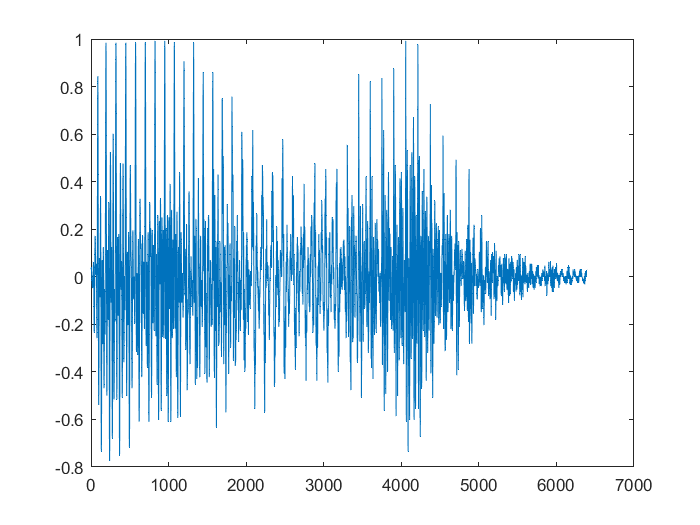

x_min = find(audioData>0.03,1); % Obtiene el primer índice que no es cero
x_max = find(audioData>0.03,1,'last'); % Obtiene el último índice que no es cero
palabra = audioData(x_min:x_max)';
plot(palabra)

Para revisar el audio sin silencios se crea un objeto audioplayer a partir de la señal obtenida en el punto anterior.

audioPalabra = audioplayer(palabra,fs);
play(audioPalabra);